clc; close all; clearvars;

load('mats/ifiss.mat');

tau = 1e-1;
M = Mh - tau * Ah;
C = C - 1e-10*speye(size(C));
N = -tau * C;
A = -tau * B;

b0 = tau * f;
c0 = -tau * g;

[m, n] = size(A);

dM = decomposition(M, 'chol');
dN = decomposition(N, 'chol');
Mfunc = @(x, t) Mopertor(M, dM, x, t);
Nfunc = @(x, t) Mopertor(N, dN, x, t); 

exres = true;
show_info = true;
tol = 1e-10;

stol = 1e-10;
k = 40;
p = 120;
maxcycle = 10;
maxit = 4000;

num_rhs = 10;

resvec1 = [];
resvec2 = [];
resvec3 = [];
resvec4 = [];

% TriCG for all the systems
[x, y, ~, resvec] = tricg(A, b0, c0, Mfunc, Nfunc, tol, maxit, exres=exres, show_info=show_info);
resvec1 = [resvec1; resvec];
for i = 2:num_rhs
    b = b0 + Mh * x;
    [x, y, ~, resvec] = tricg(A, b, c0, Mfunc, Nfunc, tol, maxit, exres=exres, show_info=show_info);
    resvec1 = [resvec1; resvec];
end

% MINRES for all the systems
K = [M, A; A', -N];
pre = @(x, t) [Mfunc(x(1:m), t); Nfunc(x(m+1:end), t)];
[x, ~, resvec] = minres(K, [b0; c0], pre, tol, maxit, exres=exres);
resvec2 = [resvec2; resvec];
for i = 2:num_rhs
    b = b0 + Mh * x(1:m);
    [x, ~, resvec] = minres(K, [b; c0], pre, tol, maxit, exres=exres);
    resvec2 = [resvec2; resvec];
end

% TriCG-DR for the 1st system
[x, y, ~, resvec, U, T, V, MU, NV] = tricgdr(A, b0, c0, Mfunc, Nfunc, k, p, tol, ...
                          maxcycle, maxit=maxit, stol=stol, exres=exres);
resvec3 = [resvec3; resvec];

% D-TriCG for the 2nd to the last systems
for i = 2:num_rhs
    b = b0 + Mh * x;
    d1 = [eye(k), T(1:k, 1:k); T(1:k, 1:k)', -eye(k)] \ [U(:,1:k)'*b; V(:,1:k)'*c0];
    d2 = [eye(k+1, k), T(1:k+1, 1:k); T(1:k, 1:k+1)', -eye(k+1, k)] * d1;
    rx = b - MU(:, 1:k+1) * d2(1:k+1);
    ry = c0 - NV(:, 1:k+1) * d2(k+2:end);

    [dx, dy, ~, resvec] = tricg(A, rx, ry, Mfunc, Nfunc, tol, maxit, exres=exres, show_info=show_info, ...
        augU=U(:,1:k), augMU=MU(:,1:k), augV=V(:,1:k), augNV=NV(:,1:k));
    x = U(:, 1:k) * d1(1:k) + dx;
    y = V(:, 1:k) * d1(k+1:end) + dy;

    resvec3 = [resvec3; resvec];
end

% TriCG-DR for all the systmes
% [x, y, ~, resvec] = tricgdr(A, b0, c0, Mfunc, Nfunc, k, p, tol, ...
%                                 maxcycle, maxit=maxit, stol=stol, exres=exres);
% resvec4 = [resvec4; resvec];
% for i = 2:num_rhs
%     b = b0 + Mh * x;
%     [x, y, ~, resvec] = tricgdr(A, b, c0, Mfunc, Nfunc, k, p, tol, ...
%                                 maxcycle, maxit=maxit, stol=stol, exres=exres);
%     resvec4 = [resvec4; resvec];
% end

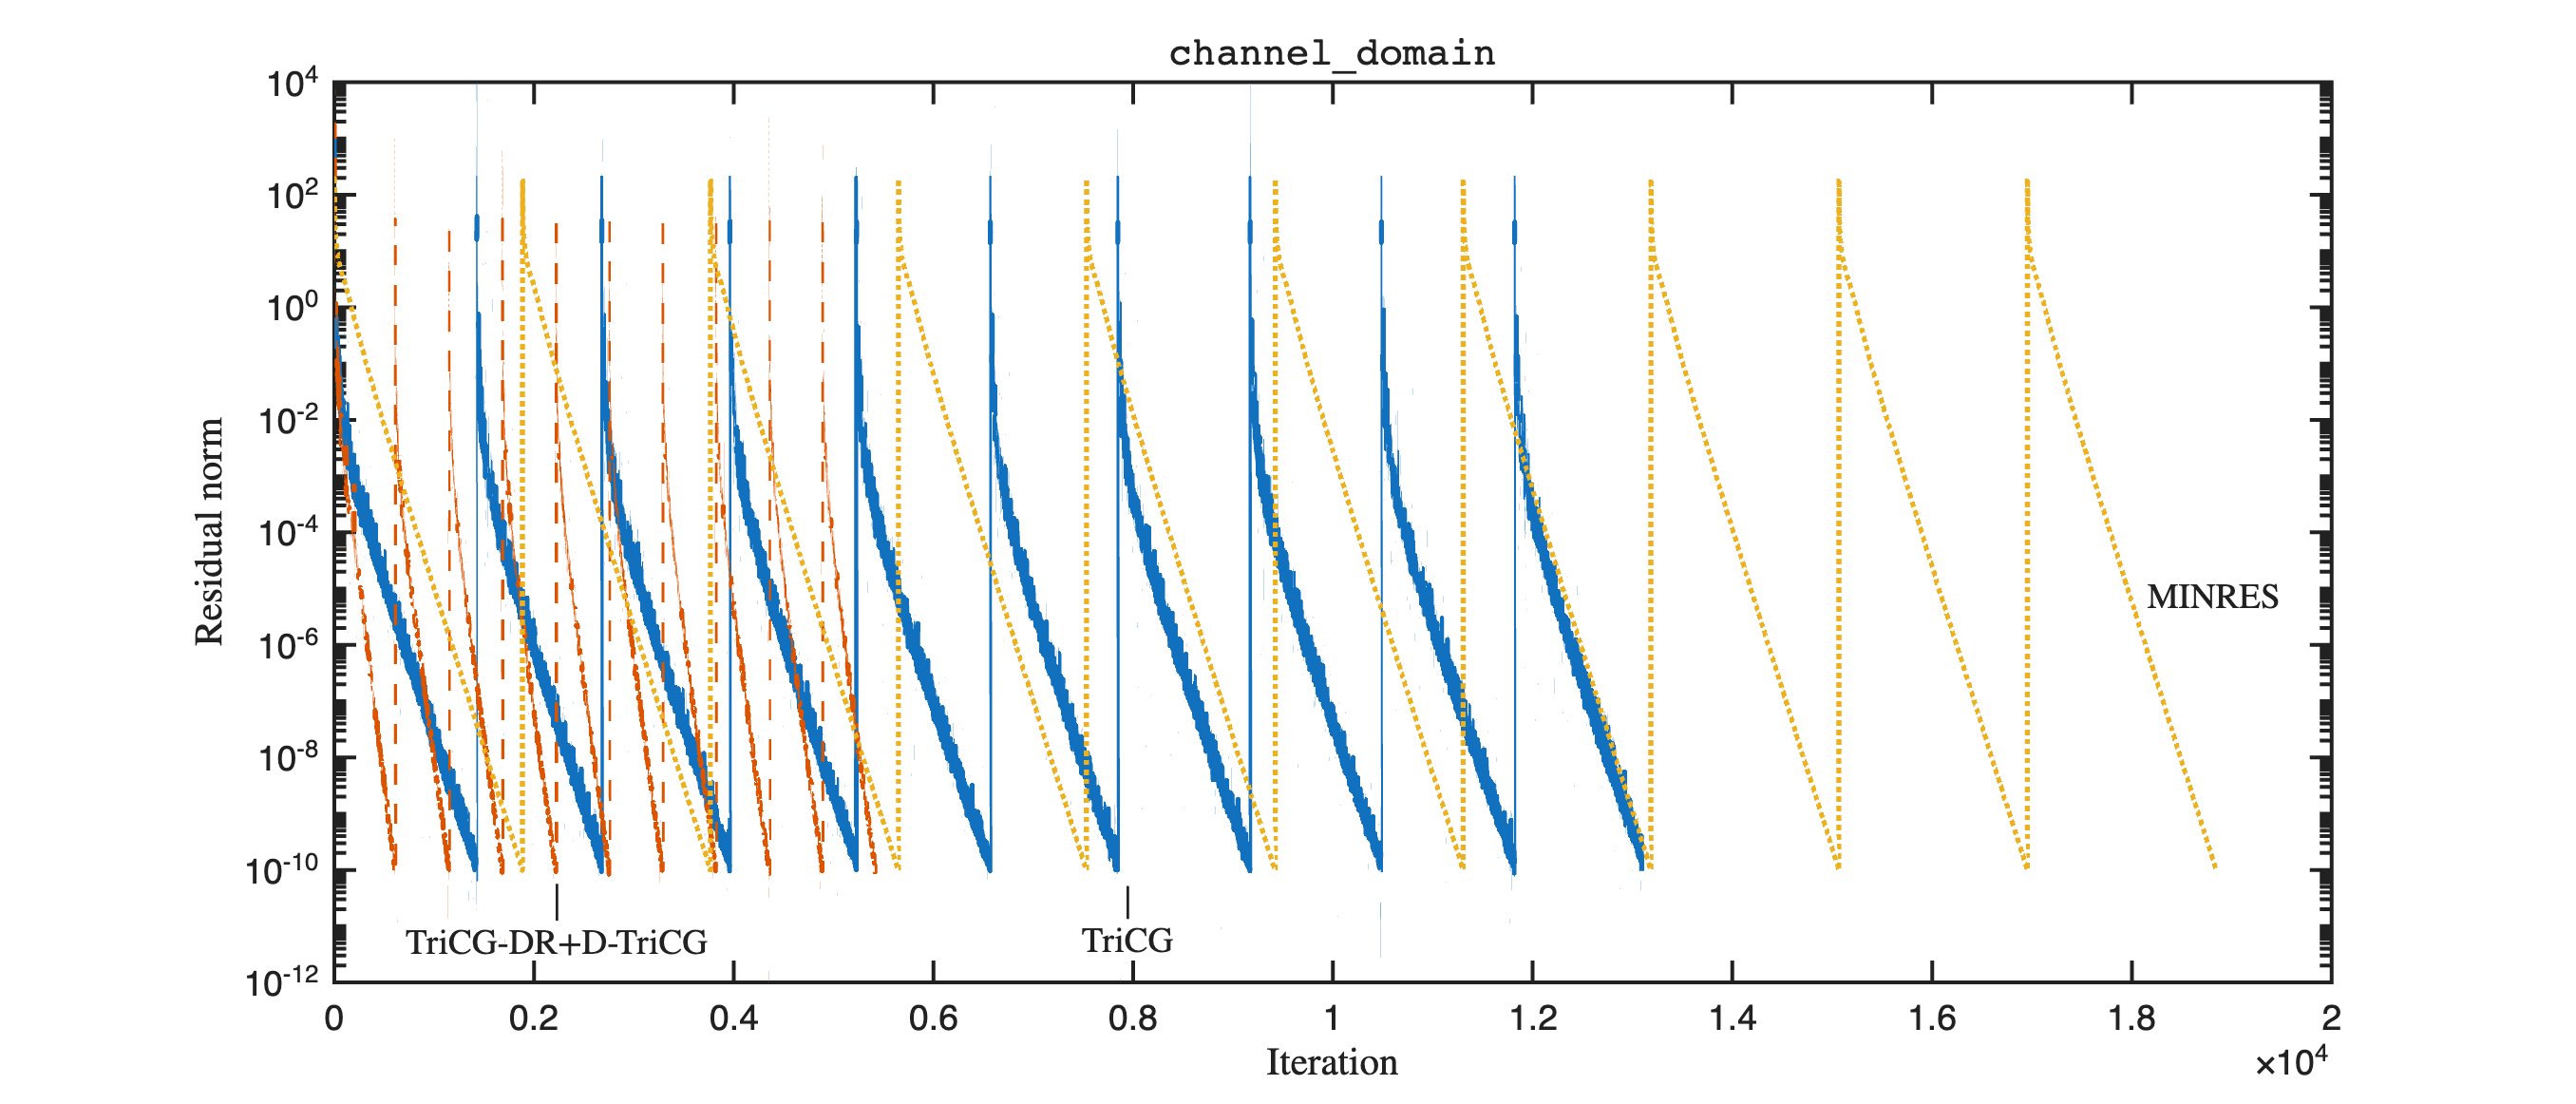

default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 1400 600]);

p1 = semilogy(0:length(resvec1)-1, resvec1, LineStyle='-');
hold on;
p2 = semilogy(0:length(resvec3)-1, resvec3, LineStyle='--');
p3 = semilogy(0:length(resvec2)-1, resvec2, LineStyle=':');
hold off;

% ylim([1e-12, 1e4]);
title('\texttt{channel\_domain}', Interpreter='latex', FontSize=18);
xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
% legend([p1, p3, p2], {'TriCG', 'MINRES', 'TriCG-DR+D-TriCG$\ $'}, Location='northeast', ...
%     Interpreter='latex', FontSize=14);

annotation("textarrow", [0.2162 0.2162], [0.166 0.1994], "String", "TriCG-DR+D-TriCG", ...
            "FontSize", 14, "LineWidth", 1, "HeadStyle", "none", "Interpreter", "latex");
annotation("textarrow", [0.4378 0.4378], [0.1677 0.1974], "String", "TriCG", ...
            "FontSize", 14, "LineWidth", 1, "HeadStyle", "none", "Interpreter", "latex");
annotation("textbox", [0.8273 0.4374 0.1138 0.04874], "String", "MINRES", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");


exportgraphics(gcf, 'figs/fig5.pdf', Resolution=600);